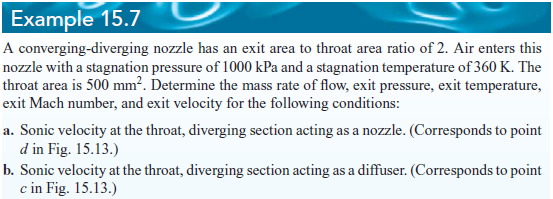

# given

u = symunit;
Ae = 1000*u.mm^2;
At = 500*u.mm^2;
po = 1000*u.kPa;
To = 360*u.K;
pb = [800; 528; 300]*u.kPa;
air = ig;

# exit Mach numbers

syms M;
Me = sym.zeros(2,1);
f = matlabFunction(air.A_As(M)-Ae/At);
Me(1) = fzero(f, [1 12]); % supersonic exit flow
Me(2) = fzero(f, [0.1 1]); % subsonic exit flow
Me_vpa = vpa(Me, 4) %#ok

$$Me\_vpa = \left(\begin{array}{c} 2.197\\ 0.3059 \end{array}\right)$$

clear Me_vpa;

# exit flow data

pe = po*air.p_po(Me);
pe_vpa = vpa(pe, 5) %#ok

$$pe\_vpa = \left(\begin{array}{c} 93.933\,\mathrm{kPa}\\ 937.16\,\mathrm{kPa} \end{array}\right)$$

Te = To*air.T_To(Me);
Te_vpa = vpa(Te, 5) %#ok

$$Te\_vpa = \left(\begin{array}{c} 183.16\,K\\ 353.39\,K \end{array}\right)$$

rhoe = pe./(air.R*Te);
Ve = rewrite(Me.*sqrt(air.gamma*air.R*Te), 'SI');
Ve = simplify(Ve, 'IgnoreAnalyticConstraints', true);
Ve_vpa = vpa(Ve, 5) %#ok

$$Ve\_vpa = \left(\begin{array}{c} 596.05\,\frac{m}{s}\\ 115.27\,\frac{m}{s} \end{array}\right)$$

mdot = rewrite(rhoe*Ae.*Ve, 'SI');
mdot_vpa = vpa(mdot, 3) %#ok

$$mdot\_vpa = \left(\begin{array}{c} 1.07\,\frac{\mathrm{kg}}{s}\\ 1.07\,\frac{\mathrm{kg}}{s} \end{array}\right)$$

clear pe_vpa Te_vpa Ve_vpa mdot_vpa;